**Normalisation of data**

clc

data=readtable("AverageLift.csv","ReadVariableNames",0);
data=table2array(data)

data =    20.0000         0   20.0000    0.6600
   20.0000         0   50.0000    0.5660
   20.0000  100.0000   20.0000    1.0073
   20.0000  100.0000   50.0000    0.8639
  200.0000         0   20.0000    0.7093
  200.0000         0   50.0000    0.6375
  200.0000  100.0000   20.0000    1.1048
  200.0000  100.0000   50.0000    0.9233
   20.0000   50.0000   35.0000    0.7662
  200.0000   50.0000   35.0000    0.8378


table_heads=['Re','Overlap','AOA','COL']

table_heads = 'ReOverlapAOACOL'

x=data(:,1:3);
y=data(:,4);

x1_min=min(x(:,1))

x1_min = 20

x1_max=max(x(:,1))

x1_max = 200

x2_min=min(x(:,2))

x2_min = 0

x2_max=max(x(:,2))

x2_max = 100

x3_min=min(x(:,3))

x3_min = 20

x3_max=max(x(:,3))

x3_max = 50


x_norm=[];
for i=1:width(x)
    temp=x(:,i);
    temp=(temp-min(temp))/(max(temp)-min(temp));
    x_norm=[x_norm,temp];
end
x_norm

x_norm =          0         0         0
         0         0    1.0000
         0    1.0000         0
         0    1.0000    1.0000
    1.0000         0         0
    1.0000         0    1.0000
    1.0000    1.0000         0
    1.0000    1.0000    1.0000
         0    0.5000    0.5000
    1.0000    0.5000    0.5000



x_train=x_norm(1:30,:);
y_train=y(1:30,:);

x_test=x_norm(31:end,:);
y_test=y(31:end,:);


[f1_m, f2_m, f3_m]=meshgrid(0:0.05:1,0:0.05:1,0:0.05:1);

f1=reshape(f1_m,[],1);
f2=reshape(f2_m,[],1);
f3=reshape(f3_m,[],1);
size(f1_m)

ans =     21    21    21


x_temp=[];
for i=0:0.05:1
    for j=0:0.05:1
        for k=0:0.05:1
            x_temp=[x_temp;i,j,k];
        end
    end
end




**Bayesian Optimisation **

%n=input("Number of iteration for bayesian optimisation: ");

model=fitrgp(x_train,y_train);

lambda=[10];

losses=[];

loss_test=0;

loss_test = 0

for j=lambda
    for i=1:0
        model=fitrgp(x_train,y_train);
        acquisiton=@(l)(-1*(-1*predict(model, [l(1),l(2),l(3)])+10*Out2(@predict,model,[l(1),l(2),l(3)])));
        
        y_temp=[];
        for i=1:length(x_temp)
            temp=x_temp(i,:);
            y_temp=[y_temp;-1*acquisiton(temp)];
        end
        
        x_test1=x_temp
        
        figure 
        s=scatter3(x_test1(:,1),x_test1(:,2),x_test1(:,3),200,y_temp,"filled");
        xlabel("x1");
        ylabel("x2");
        zlabel("x3");
        colorbar

        %for k=0:0.1:1
        %    f=@(a,b)(-1*(-1*predict(model, [a,b,k])+10*Out2(@predict,model,[a,b,k])));
        %    figure
        %    fmesh(f)
        %    colorbar
        %end
        %acquisiton1=@(a,b,c)(-1*(-1*predict(model, [a,b,c])+10*Out2(@predict,model,[a,b,c])));
        %[X,Y,Z] = meshgrid(0:0.1:1); 
        %V = acquisiton1(X,Y,Z)
        %isosurface(X,Y,Z,V);
        lb = [0,0,0];
        ub = [1,1,1];
        x0=[0,0,0];
        gs = GlobalSearch;


        problem = createOptimProblem('fmincon','x0',x0,'ub',ub,'lb',lb,'objective',acquisiton);
        l_opt=run(gs,problem)
        x1=(l_opt(1))*(x1_max-x1_min)+x1_min;
        x2=(l_opt(2))*(x2_max-x2_min)+x2_min;
        x3=(l_opt(3))*(x3_max-x3_min)+x3_min;
        x_train=[x_train;l_opt];
        temp=input("Value of y at "+string(x1)+" , "+string(x2)+" , "+string(x3)+" : ");
        y_train=[y_train;temp];
        loss_test=Loss_grp(model,x_test,y_test)*100;

        if (loss_test<=0.05)
            fprintf("Error percent is: %d",loss_test);
            break
        end
    end
    losses=[losses,loss_test];
    fprintf("\nError percent is: %d",loss_test);
end


Error percent is: 0


%plot(lambda,losses,"Color","red");

**Plotting the final Function**

y_temp=[];

for i=1:length(x_temp)
    temp=x_temp(i,:);
    y_temp=[y_temp;predict(model,temp)];
end

y_new=[]


y_new =

     []



for i=1:length(f1)
    temp=[f1(i),f2(i),f3(i)];
    y_new=[y_new;predict(model,temp)];
end

y_new=reshape(y_new,size(f1_m));
y_new

y_new = y_new(:,:,1) =

    0.6600    0.6629    0.6659    0.6691    0.6724    0.6757    0.6790    0.6823    0.6856    0.6888    0.6919    0.6948    0.6975    0.7001    0.7023    0.7043    0.7060    0.7074    0.7084    0.7090    0.7093
    0.6669    0.6699    0.6731    0.6764    0.6797    0.6832    0.6867    0.6902    0.6936    0.6970    0.7003    0.7034    0.7063    0.7090    0.7115    0.7137    0.7156    0.7172    0.7184    0.7192    0.7197
    0.6744    0.6775    0.6807    0.6841    0.6877    0.6913    0.6949    0.6985    0.7022    0.7057    0.7091    0.7125    0.7156    0.7185    0.7212    0.7236    0.7257    0.7275    0.7290    0.7300    0.7307
    0.6826    0.6857    0.6891    0.6926    0.6962    0.6999    0.7037    0.7075    0.7113    0.7150    0.7186    0.7221    0.7255    0.7286    0.7315    0.7342    0.7365    0.7385    0.7402    0.7415    0.7424
    0.6916    0.6948    0.6982    0.7018    0.7055    0.7093    0.7132    0.7172    0.7211    0.7250    0.7288    0.7325    0.7360  

T=array2table([f1,f2,f3,reshape(y_new,[],1)])

T = 9261×4 table
    Var1    Var2    Var3     Var4  
    ____    ____    ____    _______

     0         0     0         0.66
     0      0.05     0       0.6669
     0       0.1     0      0.67439
     0      0.15     0      0.68258
     0       0.2     0      0.69157
     0      0.25     0      0.70145
     0       0.3     0      0.71232
     0      0.35     0      0.72428
     0       0.4     0      0.73742
     0      0.45     0      0.75181
     0       0.5     0      0.76754
     0      0.55     0      0.78467
     0       0.6     0      0.80325
     0      0.65     0      0.82333
     0       0.7     0      0.84495
     0      0.75     0      0.86813


writetable(T, 'plotting_data.csv', 'WriteVariableNames', true)

k=0:0.05:1;
% sliceomatic(y_new,k,k,k);
x_test=x_temp

x_test =          0         0         0
         0         0    0.0500
         0         0    0.1000
         0         0    0.1500
         0         0    0.2000
         0         0    0.2500
         0         0    0.3000
         0         0    0.3500
         0         0    0.4000
         0         0    0.4500


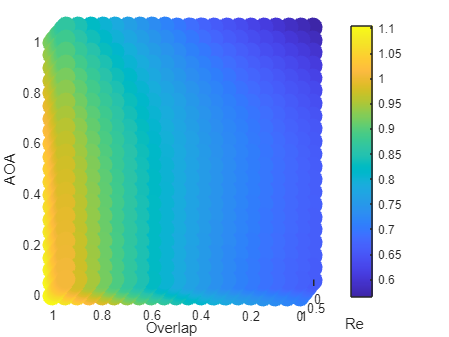

s=scatter3(x_test(:,1),x_test(:,2),x_test(:,3),200,y_temp,"filled","o");
xlabel("Re");
ylabel("Overlap");
zlabel("AOA");
colorbar

function Z = Out2(FUN,varargin)
% Z = Out2(FUN,VARARGIN);
%
%	Provides the second output from the function

[~,Z] = FUN(varargin{:});
end
